HW3 - Exercise 1b

[A1] Traditional

x = linspace(1.5, 2.5, 10000); 
n = 13;

px_A1 = 1; 
for i = 1:n
    px_A1 = px_A1 .* (x - 2);
end

px_A1

px_A1 = 1.0e-03 *

   -0.1221   -0.1218   -0.1214   -0.1211   -0.1208   -0.1205   -0.1202   -0.1199   -0.1196   -0.1192   -0.1189   -0.1186   -0.1183   -0.1180   -0.1177   -0.1174   -0.1171   -0.1168   -0.1165   -0.1162   -0.1159   -0.1156   -0.1153   -0.1150   -0.1147   -0.1144   -0.1141   -0.1138   -0.1135   -0.1132   -0.1129   -0.1126   -0.1123   -0.1120   -0.1117   -0.1114   -0.1111   -0.1108   -0.1105   -0.1103   -0.1100   -0.1097   -0.1094   -0.1091   -0.1088   -0.1085   -0.1082   -0.1080   -0.1077   -0.1074


Coefficients:

c = poly(ones(n,1)*2);
c

c =            1         -26         312       -2288       11440      -41184      109824     -219648      329472     -366080      292864     -159744       53248       -8192


[A2] Horner's:

px_A2 = c(1); 
for i = 2:n+1
    px_A2 = c(i) + x.*px_A2;
end
px_A2

px_A2 = 1.0e-03 *

   -0.1221   -0.1218   -0.1214   -0.1211   -0.1208   -0.1205   -0.1202   -0.1199   -0.1196   -0.1192   -0.1189   -0.1186   -0.1183   -0.1180   -0.1177   -0.1174   -0.1171   -0.1168   -0.1165   -0.1162   -0.1159   -0.1156   -0.1153   -0.1150   -0.1147   -0.1144   -0.1141   -0.1138   -0.1135   -0.1132   -0.1129   -0.1126   -0.1123   -0.1120   -0.1117   -0.1114   -0.1111   -0.1108   -0.1105   -0.1103   -0.1100   -0.1097   -0.1094   -0.1091   -0.1088   -0.1085   -0.1082   -0.1080   -0.1077   -0.1074


ds

% xtoi=1; px=c(n+1); 
% for i=n:-1:1
%     xtoi = xtoi.*x; 
%     px=px+c(i).*xtoi;
% end
% px

[A3] 

if (c(n+1) > 0)
    pos=c(n+1); 
    neg=0; 
else 
    neg=c(n+1);
    pos=0;
end; 
xtoi=1;
for i=n:-1:1
    xtoi = xtoi.*x; 
    dsum = c(i).*xtoi;
    if (dsum > 0) 
        pos=pos+dsum; 
    else neg=neg+dsum;
    end;
    pos+neg;
end; 
px_A3=pos+neg

px_A3 = 1.0e-03 *

   -0.1221   -0.1218   -0.1214   -0.1211   -0.1208   -0.1205   -0.1202   -0.1199   -0.1196   -0.1192   -0.1189   -0.1186   -0.1183   -0.1180   -0.1177   -0.1174   -0.1171   -0.1168   -0.1165   -0.1162   -0.1159   -0.1156   -0.1153   -0.1150   -0.1147   -0.1144   -0.1141   -0.1138   -0.1135   -0.1132   -0.1129   -0.1126   -0.1123   -0.1120   -0.1117   -0.1114   -0.1111   -0.1108   -0.1105   -0.1103   -0.1100   -0.1097   -0.1094   -0.1091   -0.1088   -0.1085   -0.1082   -0.1080   -0.1077   -0.1074


Plots:

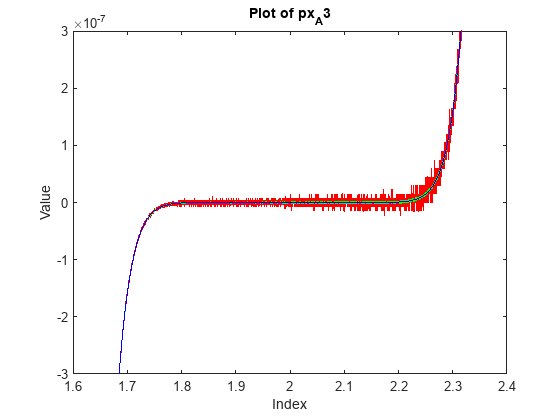

figure; 
plot(x, px_A3, 'r'); 
hold on;
% ylim([-3E-7, 3E-7]);
% title('Plot of px_A1');
% xlabel('Index');
% ylabel('Value');

% figure; 
plot(x, px_A2, 'g'); 
% ylim([-3E-7, 3E-7]); 
% title('Plot of px_A2');
% xlabel('Index');
% ylabel('Value');

% figure;
plot(x, px_A1, 'b'); 
hold off;
ylim([-3E-7, 3E-7]); 
title('Plot of px_A3');
xlabel('Index');
ylabel('Value');

Relative errors of A2 and A3 wrt A1:

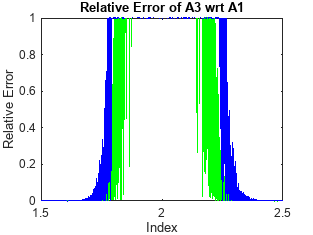

relativeErrorPx_A2 = abs((px_A2 - px_A1) ./ px_A1);
relativeErrorPx_A3 = abs((px_A3 - px_A1) ./ px_A1);

% Plot the relative error of px_A2
figure; 
plot(x, relativeErrorPx_A2, 'g'); 
hold on;
% ylim([0, 1]); 
% title('Relative Error of A2 wrt A1');
% xlabel('Index');
% ylabel('Relative Error');

% figure; 
plot(x, relativeErrorPx_A3, 'b'); 
hold off;
ylim([0, 1]); 
title('Relative Error of A3 wrt A1');
xlabel('Index');
ylabel('Relative Error');

Zoomed into range x in [2-eps, 2+eps]

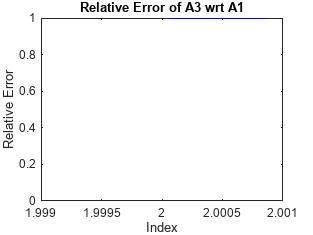

radius = 1E-3;

% Plot the relative error of px_A2
figure; 
plot(x, relativeErrorPx_A2, 'g'); 
hold on;
% ylim([0, 1E3]);
% xlim([2-radius, 2+radius]);
% title('Relative Error of A2 wrt A1');
% xlabel('Index');
% ylabel('Relative Error');

% figure; 
plot(x, relativeErrorPx_A3, 'b'); 
hold off;
xlim([2-radius, 2+radius]);
ylim([0, 1]); 
title('Relative Error of A3 wrt A1');
xlabel('Index');
ylabel('Relative Error');